sm = SessManager;
d = sm.cons_usable(sm.special_sessions_usable_index_single('Mouse2028'));

Total trials: 358	Throwing away 0	keeping 358


load(d.source_path);
X = tracesEvents.rawTraces;
E = hyperdetect(X, 'z_val', 3, 'OutType', 'onset', 'Progress', true);

Detecting 257 cells
200
Done


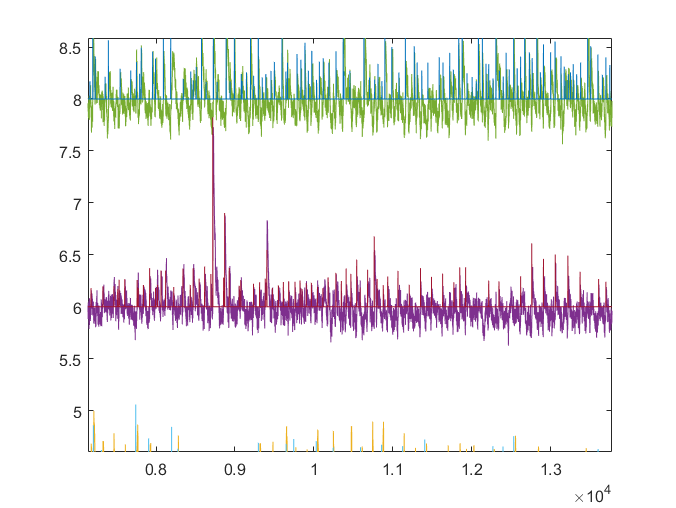

figure;

n_sel = 10;
idx = randperm(size(X,2), n_sel);
gaps = (0:n_sel - 1)*2;
X_sub = X(:, idx) + gaps;
E_sub = E(:, idx) + gaps;

plot(X_sub); hold on
plot(E_sub);